Glaucoma 11 - similar a glaucoma 9 pero menos punto en el borde

% clear; close all; clc
% 
% addpath(genpath("images"));
% addpath(genpath("images separadas\prueba_ROI_2"));
% 
T = readtable("metadata.csv");
% 
% Revisada_B = Metadata.quality==4;
% 
% T = Metadata(Revisada_B,:)
% 
% [N, P] = size(T)

% tick = zeros(length(T.image),1); 
% 
% for i = 1:N
%     file = T.image{i};
%     I = imload(file);
%     if I(146,2611) > 0.9
%         tick(i) = 1;
%     end
% end    
% 
% list = find(tick==0)

file = T.image{1540} %list(7)}

file = 'image_1540.jpg'

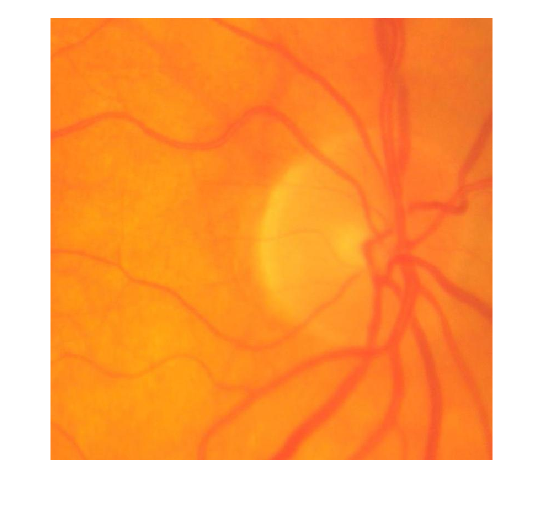

file = {['ROI_' file]};
I = imread(file{1});
I_g = im2double(rgb2gray(I));

figure, imshow(I)

sizes = size(I)

sizes =    801   801     3


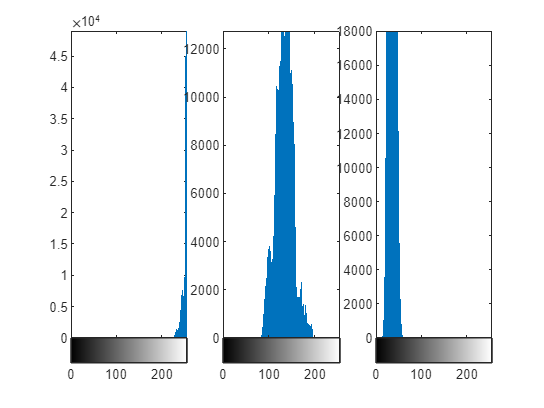

n_pixel = sizes(1)*sizes(2);

I1 = I(:,:,1);
I2 = I(:,:,2);
I3 = I(:,:,3);

figure
subplot(131), imhist(I1)
subplot(132), imhist(I2)
subplot(133), imhist(I3)

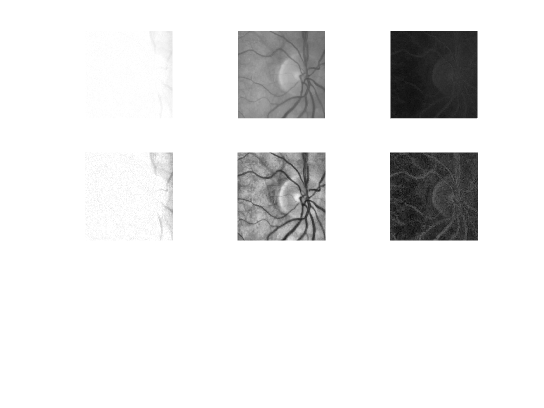


figure
subplot(331), imshow(I1)
subplot(332), imshow(I2)
subplot(333), imshow(I3)
 
I1 = adapthisteq(I1);
I2 = adapthisteq(I2);
I3 = adapthisteq(I3);

subplot(334),imshow(I1)
subplot(335),imshow(I2)
subplot(336),imshow(I3)


m1 = double([max(max(I(:,:,1))) min(min(I(:,:,1))) mean2(I(:,:,1)) std2(I(:,:,1))])

m1 =    255   218   253     4


m2 = double([max(max(I(:,:,2))) min(min(I(:,:,2))) mean2(I(:,:,2)) std2(I(:,:,2))])

m2 =    198    80   134    19


m3 = double([max(max(I(:,:,3))) min(min(I(:,:,3))) mean2(I(:,:,3)) std2(I(:,:,3))])

m3 =     64    12    36     9



m1 = double([max(max(I1)) min(min(I1)) mode(I1(:)) mean2(I1) std2(I1) ])

m1 =    255   147   255   247    14


m2 = double([max(max(I2)) min(min(I2)) mode(I2(:)) mean2(I2) std2(I2)])

m2 =    242    33   151   139    33


m3 = double([max(max(I3)) min(min(I3)) mode(I3(:)) mean2(I3) std2(I3)])

m3 =    104    10    51    53    14



m1(6)=round((mean([m1(3),m1(4)])))

m1 =    255   147   255   247    14   251


m2(6)=round((mean([m2(3),m2(4)])))

m2 =    242    33   151   139    33   145


m3(6)=round((mean([m3(3),m3(4)])))

m3 =    104    10    51    53    14    52


Disc segmentation

threshold = [min([0.99 m1(4)*1.1/255]),m2(4)*1.2/255,m3(4)*1.3/255]

threshold =     0.9900    0.6541    0.2702


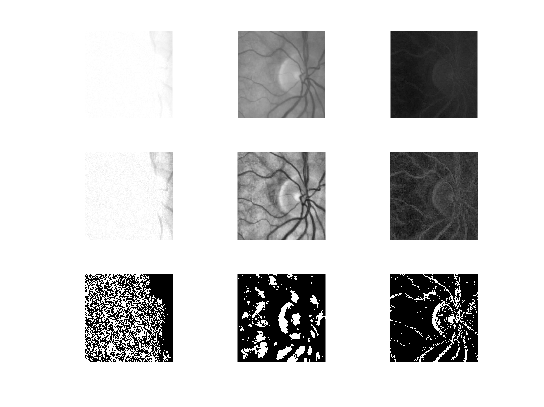

% threshold = [min([0.99 m1(3)*1.1/255]),m2(3)*1.2/255,m3(3)*1.3/255]
% threshold = [min([0.99 m1(6)*1.1/255]),m2(6)*1.2/255,m3(6)*1.3/255]

IB1 = imbinarize(I1,threshold(1));
IB2 = imbinarize(I2,threshold(2));
IB3 = imbinarize(I3,threshold(3));

% figure
subplot(337),imshow(IB1)
subplot(338),imshow(IB2)
subplot(339),imshow(IB3)

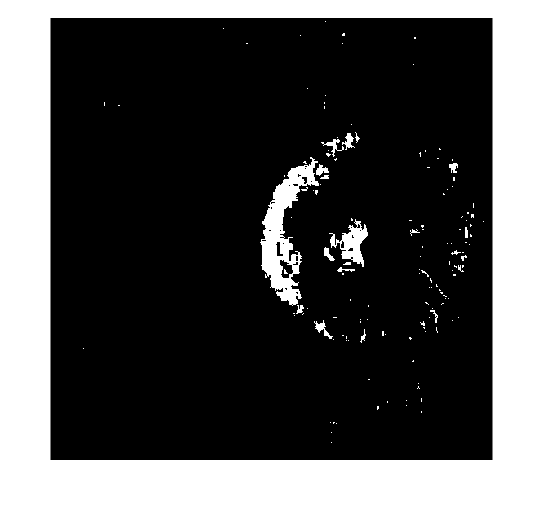


figure, 
imshow(IB2.*IB3)

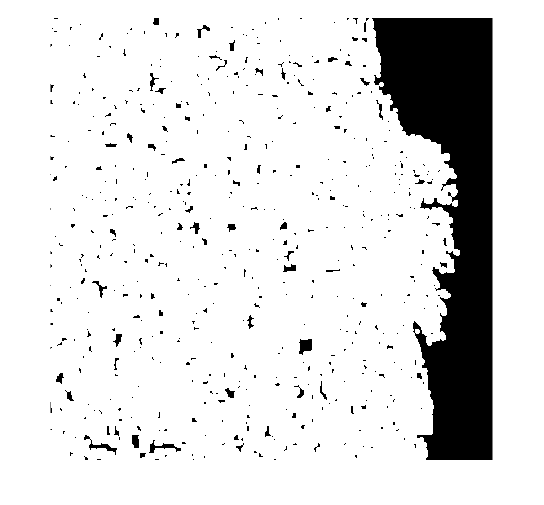

P = imdilate(IB1,strel('disk',5));
P = bwareafilt(P,1);
figure, imshow(P)

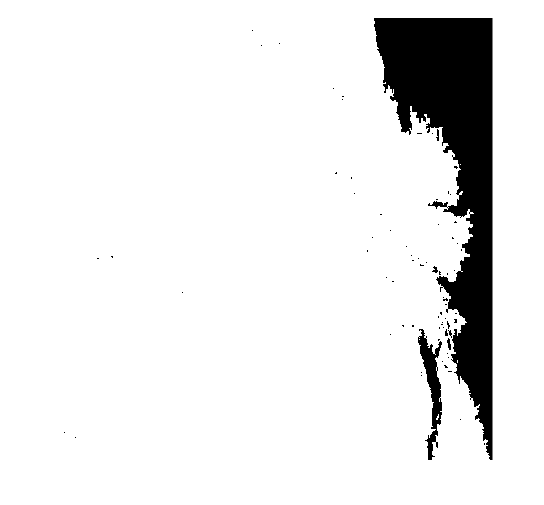


se = strel('disk',2);
P = imclose(P,se);
P2 = imfill(P,'holes');

% Compute the global threshold using Otsu's method
threshold = graythresh(I1);

% Binarize the image using the threshold
P = imbinarize(I1, threshold);
P = bwareafilt(P,1);

figure
imshow(P)


% Calcular el número de píxeles en común
pixelesEnComun1 = sum(P(:) & IB1(:));
pixelesEnComun2 = sum(P(:) & IB2(:));
pixelesEnComun3 = sum(P(:) & IB3(:));


% Calcular el porcentaje de píxeles en común
porcentaje1 = (pixelesEnComun1 / max(sum(P(:)==1),sum(IB1(:)==1))) * 100

porcentaje1 = 46.5442

porcentaje2 = (pixelesEnComun2 / max(sum(P(:)==1),sum(IB2(:)==1))) * 100

porcentaje2 = 22.1707

porcentaje3 = (pixelesEnComun3 / max(sum(P(:)==1),sum(IB3(:)==1))) * 100

porcentaje3 = 14.2713


pixelesEnComun4 = sum(P(:) & P2(:));
porcentaje4 = (pixelesEnComun4 / max(sum(P(:)==1),sum(P2(:)==1))) * 100

porcentaje4 = 96.0844


% pixelesEnComun4 = sum(P(:) & P2(:))
% porcentaje4 = (pixelesEnComun4 / max(sum(P(:)==1),sum(P2(:)==1))) * 100

if porcentaje2>60 && porcentaje3>60 && porcentaje4>60
    4
    I7 = activecontour(I_g, P, 'Chan-vese');
    I8 = activecontour(I_g, P, 'edge');
    I9 = I7+I8;
    I9 = imbinarize(I9,0);
    figure, imshow(I9)
end

% 
% [B,L] = bwboundaries(P,'noholes');
% 
% s = zeros(1,length(B));
% 
% for k = 1:length(B)
%   s(k) = size(B{k},1);
% end
% 
% [a,b] = maxk(s,2);
% 
% for k = b 
%   boundary = B{k};
%   plot(boundary(:,2), boundary(:,1),'LineWidth',1, 'Color', 'r')    
% end
% 
% stats = regionprops(L,'Area','Centroid');
% 
% threshold = 0.94;
% 
% % loop over the boundaries
% for k = 1:length(B)
% 
%   % obtain (X,Y) boundary coordinates corresponding to label 'k'
%   boundary = B{k};
% 
%   % compute a simple estimate of the object's perimeter
%   delta_sq = diff(boundary).^2;    
%   perimeter = sum(sqrt(sum(delta_sq,2)));
%   
%   % obtain the area calculation corresponding to label 'k'
%   area = stats(k).Area;
%   
%   % compute the roundness metric
%   metric = 4*pi*area/perimeter^2;
%   
%   % display the results
%   metric_string = sprintf('%2.2f',metric);
% 
%   % mark objects above the threshold with a black circle
%   if metric > threshold
%     centroid = stats(k).Centroid;
%     plot(centroid(1),centroid(2),'ko');
%   end
%   
%   text(boundary(1,2)-35,boundary(1,1)+13,metric_string,'Color','y',...
%        'FontSize',14,'FontWeight','bold')
%   
% end
% 
% title(['Metrics Closer to 1 Indicate that ',...
%        'the Object is Approximately Round'])

contraste = stdfilt(IB1); 
cont(1) = sum(contraste(:));
contraste = stdfilt(IB2); 
cont(2) = sum(contraste(:));
contraste = stdfilt(IB3); 
cont(3) = sum(contraste(:))

cont = 1.0e+05 *

    1.1594    0.2179    0.3971



pixelesEnComun = sum(IB2(:) & IB1(:));
p1 = (pixelesEnComun / max(sum(IB2(:)==1),sum(IB1(:)==1))) * 100

p1 = 26.1014


pixelesEnComun = sum(IB2(:) & IB3(:));
p3 = (pixelesEnComun / max(sum(IB2(:)==1),sum(IB3(:)==1))) * 100

p3 = 13.2422

I4 = ones(sizes(1), sizes(2));

if m1(4)<180 && sum(IB1(:))<n_pixel*0.4 && cont(1)<4*10^4 && sum(IB3(:))>n_pixel*0.1 && p1>10
%     if sum(IB1(:))<n_pixel*0.2
%         IB1 = imdilate(IB1,strel('disk',5));
%         IB1 = bwareafilt(IB1,1);
%     end
    I4 = I4 .* IB1;
    1
end

if m2(4)>30 && sum(IB2(:))<n_pixel*0.4 && cont(2)<4*10^4 && sum(IB2(:))>n_pixel*0.05
    I4 = I4 .* IB2;
    2
end

ans = 2


if m3(4)>30 && sum(IB3(:))<n_pixel*0.4 && cont(3)<4*10^4 && sum(IB3(:))>n_pixel*0.05  && p3>10
    I4 = I4 .* IB3;
    3
end

ans = 3


figure
imshow(I4)

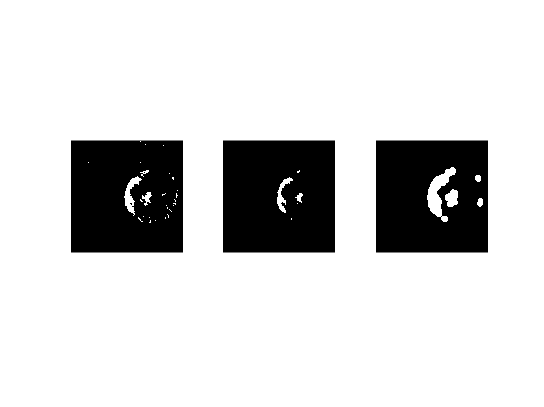

see = strel('disk',20);
see1 = strel('disk',10);
see2 = strel('disk',5);

I4 = imclose(I4,see2);
I5 = imerode(I4,see2);
I6 = imdilate(I5,see);
% I6 = imclose(I6,see1);

figure
subplot(131), imshow(I4)
subplot(132), imshow(I5)
subplot(133), imshow(I6)

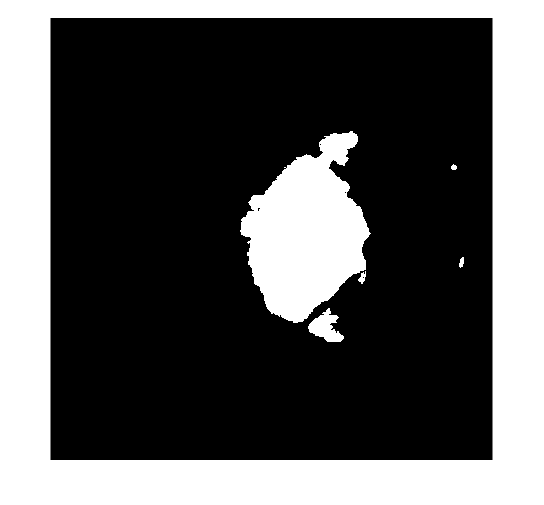


I6 = imbinarize(I6,0);
% figure, imshow(I6)

I7 = activecontour(I_g, I6, 'Chan-vese');
I8 = activecontour(I_g, I6, 'edge');
I9 = I7+I8;
I9 = imbinarize(I9,0);
figure, imshow(I9)

              chan-vese                                    edge                                        both

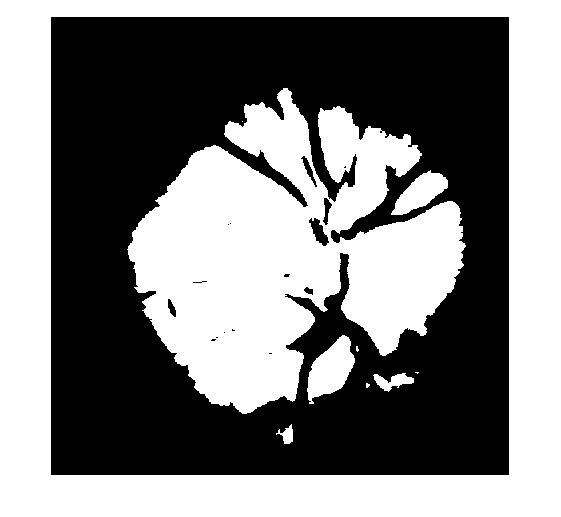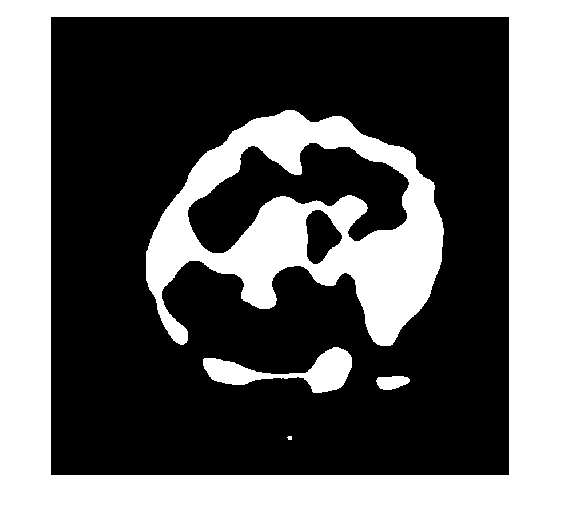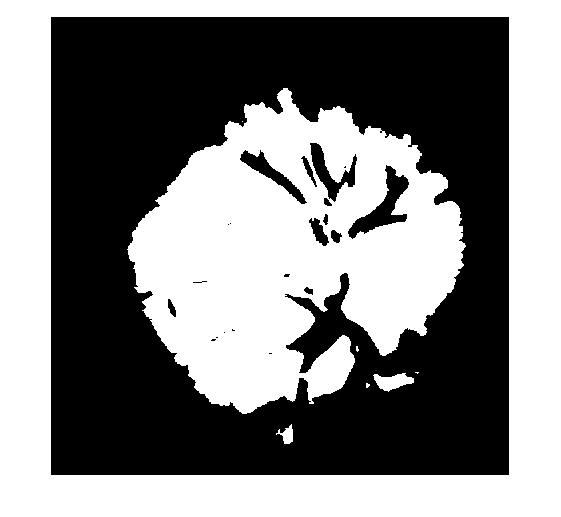

Disc = bwareafilt(I9,[1000 10000000000]);
Disc = bwareafilt(Disc,3);
Disc = imfill(Disc, 'holes');

figure, imshow(Disc)
% figure, imshow(I)
hold on

[posiciones_y, posiciones_x] = ind2sub(size(Disc), find(Disc==1));
% plot(posiciones_x,posiciones_y,'*')

centro_x1 = round(mean(posiciones_x))

centro_x1 = 472

centro_y1 = round(mean(posiciones_y))

centro_y1 = 430

plot(centro_x1,centro_y1,'o')

% Definir el radio máximo
radio_maximo = 300;
% rectangle('Position', [centro_x1-radio_maximo, centro_y1-radio_maximo, 2*radio_maximo, 2*radio_maximo], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 2);

% Crear un vector de ángulos desde 0 hasta 360 grados
% angulos = linspace(0, 2*pi, 360);
angulos = linspace(0, 2*pi, 20);

% Inicializar un vector para almacenar las coordenadas del último píxel blanco
ultimos_pixeles = zeros(size(angulos));

x_border = zeros(1,length(angulos));
y_border = zeros(1,length(angulos));
ultimo_radio = zeros(1,length(angulos));

% Recorrer cada ángulo
for i = 1:length(angulos)
    % Calcular las coordenadas del punto final de la línea
    x_final = round(centro_x1 + radio_maximo * cos(angulos(i)));
    y_final = round(centro_y1 + radio_maximo * sin(angulos(i)));

    % Obtener el perfil de intensidad a lo largo de la línea
    perfil = improfile(Disc, [centro_x1, x_final], [centro_y1, y_final],radio_maximo);
    plot([centro_x1, x_final], [centro_y1, y_final]) %plotear las lineas

    % Encontrar los índices de los píxeles blancos en el perfil
    indices_blancos = find(perfil > 0);

    if isempty(indices_blancos)
        ultimo_radio(i)=300;
    else
        % Almacenar las coordenadas del último píxel blanco
        ultimo_radio(i) = indices_blancos(end);    
    end



    x_border(i) = round(centro_x1 + ultimo_radio(i) * cos(angulos(i)));
    y_border(i) = round(centro_y1 + ultimo_radio(i) * sin(angulos(i)));
%     border(y_border(i),x_border(i)) = 1;    

end
    plot(x_border,y_border,'*','Color','r')   
    
    distancia_media = mean(ultimo_radio)

distancia_media = 170.9500

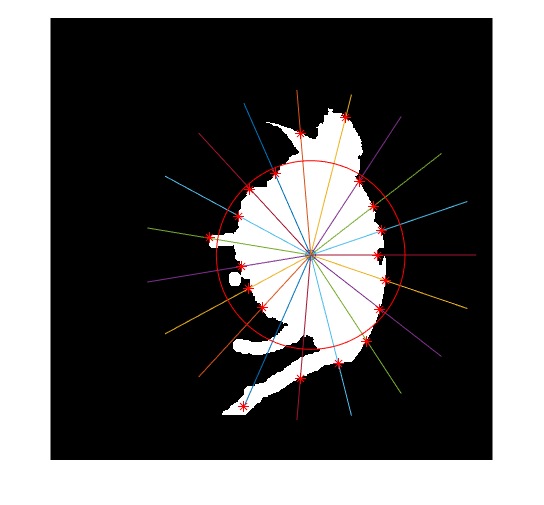

    rectangle('Position', [centro_x1-distancia_media, centro_y1-distancia_media, 2*distancia_media, 2*distancia_media], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);
    plot(x_border(1),y_border(1),'*','Color','r')   

for i = 2:length(angulos)
    if abs(ultimo_radio(i)-ultimo_radio(i-1))>100
        if abs(ultimo_radio(i)-distancia_media)<abs(ultimo_radio(i-1)-distancia_media)
                x_border(i-1) = round(centro_x1 + ultimo_radio(i) * cos(angulos(i-1)));
                y_border(i-1) = round(centro_y1 + ultimo_radio(i) * sin(angulos(i-1)));
%                 distancias(i-1) = sqrt((y_border(i-1) - centro_y2).^2 + (x_border(i-1) - centro_x2).^2);
                ultimo_radio(i-1) = ultimo_radio(i);
                plot(x_border(i-1),y_border(i-1),'*','Color','g')
        else
                x_border(i) = round(centro_x1 + ultimo_radio(i-1) * cos(angulos(i)));
                y_border(i) = round(centro_y1 + ultimo_radio(i-1) * sin(angulos(i)));
                ultimo_radio(i) = ultimo_radio(i-1);
%                 distancias(i) = sqrt((y_border(i) - centro_y2).^2 + (x_border(i) - centro_x2).^2);
                plot(x_border(i),y_border(i),'*','Color','b')
        end

%         plot(x_border(i),y_border(i),'*','Color','r')   
    end
end

figure, imshow(I)
hold on
centro_x2 = round(mean(x_border))

centro_x2 = 470

centro_y2 = round(mean(y_border))

centro_y2 = 399

distancia_media = mean(ultimo_radio)

distancia_media = 127.5000

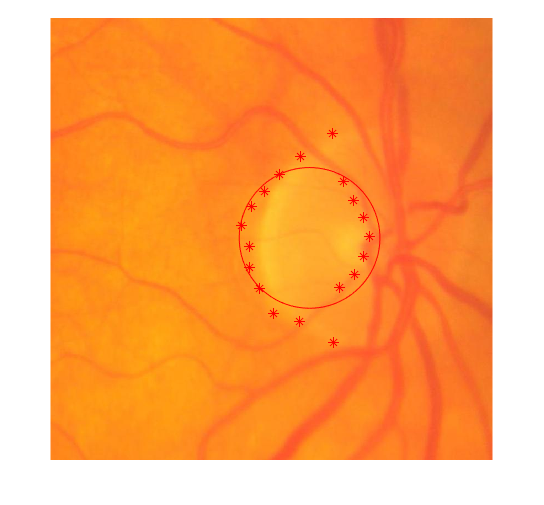

rectangle('Position', [centro_x2-distancia_media, centro_y2-distancia_media, 2*distancia_media, 2*distancia_media], 'Curvature', [1, 1], 'EdgeColor', 'r', 'LineWidth', 0.5);
plot(x_border,y_border,'*','Color','r')   

threshold2 = m2(3)*0.6/255

threshold2 = 0.3553

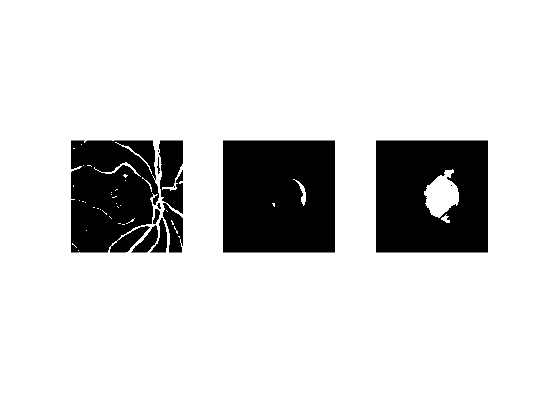

IB2 = imcomplement(imbinarize(I2,threshold2));

figure
subplot(131), imshow(IB2)

IB2 = imdilate(IB2,strel('disk',10));

radius = distancia_media;
I3 = zeros(sizes(1:2));
[x, y] = meshgrid(1:sizes(2), 1:sizes(1));
I3((x - centro_x2).^2 + (y - centro_y2).^2 <= radius^2) = 1;

IB2 = IB2 .* (I3);

subplot(132), imshow(IB2)

Disc = Disc+IB2;

subplot(133), imshow(Disc)

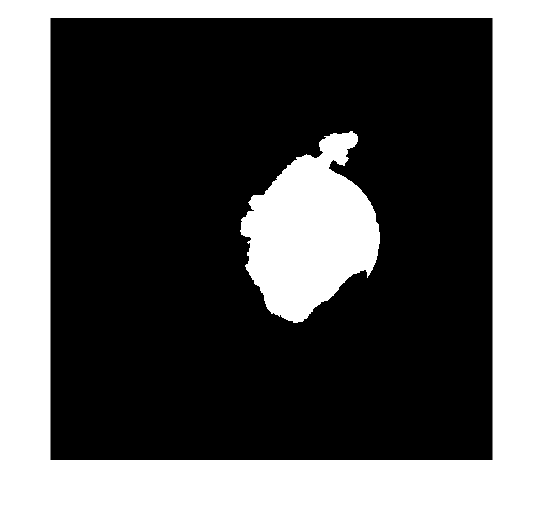



Disc = imbinarize(Disc,0);
Disc = bwareafilt(Disc,1);
Disc = imfill(Disc, 'holes');
figure
imshow(Disc)

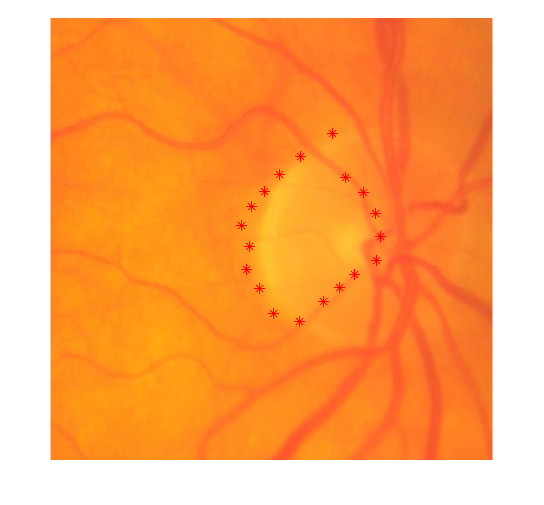

figure, imshow(I)
hold on
for i = 1:length(angulos)
    % Calcular las coordenadas del punto final de la línea
    x_final = round(centro_x1 + radio_maximo * cos(angulos(i)));
    y_final = round(centro_y1 + radio_maximo * sin(angulos(i)));

    % Obtener el perfil de intensidad a lo largo de la línea
    perfil = improfile(Disc, [centro_x1, x_final], [centro_y1, y_final],radio_maximo);
%     plot([centro_x1, x_final], [centro_y1, y_final]) %plotear las lineas

    % Encontrar los índices de los píxeles blancos en el perfil
    indices_blancos = find(perfil > 0);

    % Almacenar las coordenadas del último píxel blanco
    ultimo_radio(i) = indices_blancos(end);

    x_border(i) = round(centro_x1 + ultimo_radio(i) * cos(angulos(i)));
    y_border(i) = round(centro_y1 + ultimo_radio(i) * sin(angulos(i)));
%     border(y_border(i),x_border(i)) = 1;    

end
    plot(x_border,y_border,'*','Color','r')   

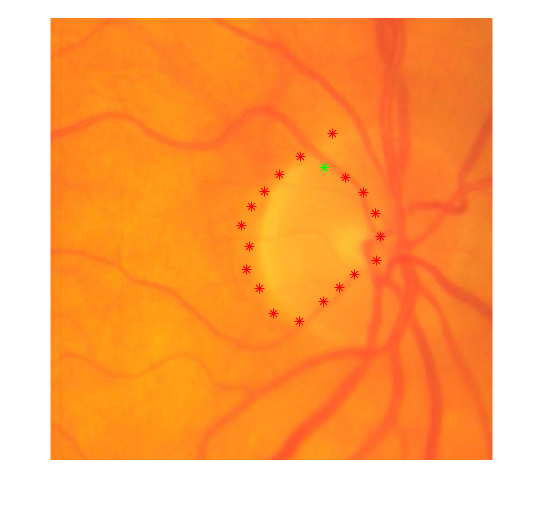

for i = 2:length(angulos)
    if abs(ultimo_radio(i)-ultimo_radio(i-1))>60
        if abs(ultimo_radio(i)-distancia_media)<abs(ultimo_radio(i-1)-distancia_media)
                x_border(i-1) = round(centro_x1 + ultimo_radio(i) * cos(angulos(i-1)));
                y_border(i-1) = round(centro_y1 + ultimo_radio(i) * sin(angulos(i-1)));
%                 distancias(i-1) = sqrt((y_border(i-1) - centro_y2).^2 + (x_border(i-1) - centro_x2).^2);
                ultimo_radio(i-1) = ultimo_radio(i);
                plot(x_border(i-1),y_border(i-1),'*','Color','g')
        else
                x_border(i) = round(centro_x1 + ultimo_radio(i-1) * cos(angulos(i)));
                y_border(i) = round(centro_y1 + ultimo_radio(i-1) * sin(angulos(i)));
                ultimo_radio(i) = ultimo_radio(i-1);
%                 distancias(i) = sqrt((y_border(i) - centro_y2).^2 + (x_border(i) - centro_x2).^2);
                plot(x_border(i),y_border(i),'*','Color','b')
        end

    end
end

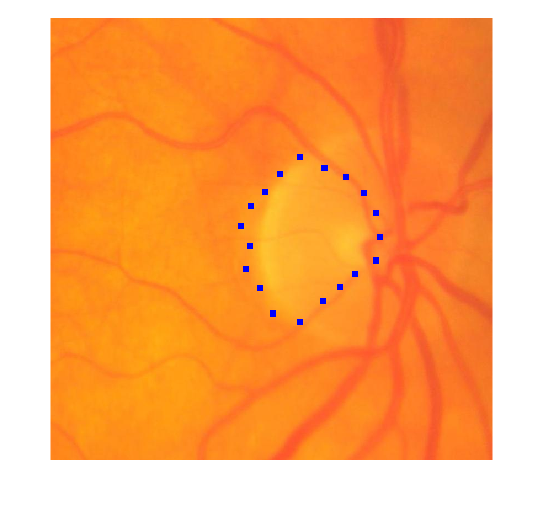

border = I;
for i =1:length(x_border)
    border(y_border(i)-5:y_border(i)+5, x_border(i)-5:x_border(i)+5,1)=0;
    border(y_border(i)-5:y_border(i)+5, x_border(i)-5:x_border(i)+5,2)=0;
    border(y_border(i)-5:y_border(i)+5, x_border(i)-5:x_border(i)+5,3)=255;
end
imshow(border)

function I = imload(file_name)
    I = imread(file_name);
    I = rgb2gray(I);                % gray scale
    I = imresize(I,[2424 3004]);    % same sizes  
    I = im2double(I);               % normalization and double format
end